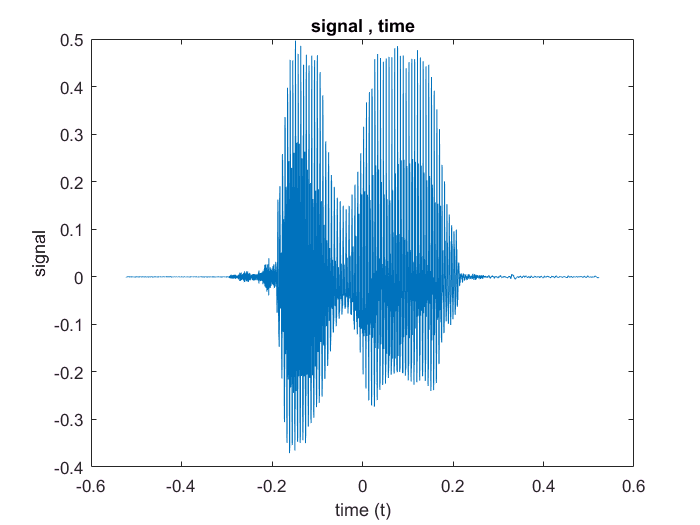

[y,fs]= audioread('data.wav');
sound(y,fs);
l = length(y);
t = -(((l-1)/fs)/2):1/fs:(((l-1)/fs)/2) ;
plot(t,y);
title('signal , time')
xlabel('time (t)')
ylabel('signal')

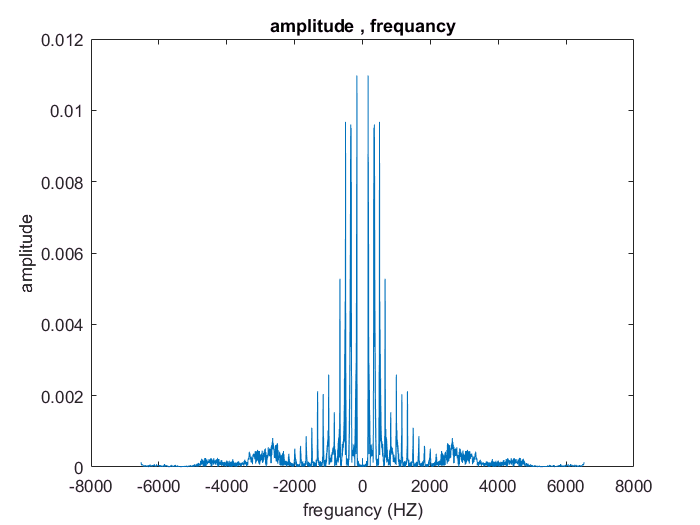

[y,fs]= audioread('data.wav');
sound(y,fs);
l = length(y);
t = -(((l-1)/fs)/2):1/fs:(((l-1)/fs)/2) ;
Y = fft(y);
Y = fftshift(Y);
f = -((length(Y)-1)/2):((length(Y)-1)/2);
A = abs(Y/length(Y));

plot(f,A);


title('amplitude , frequancy')
xlabel('freguancy (HZ)')
ylabel('amplitude')

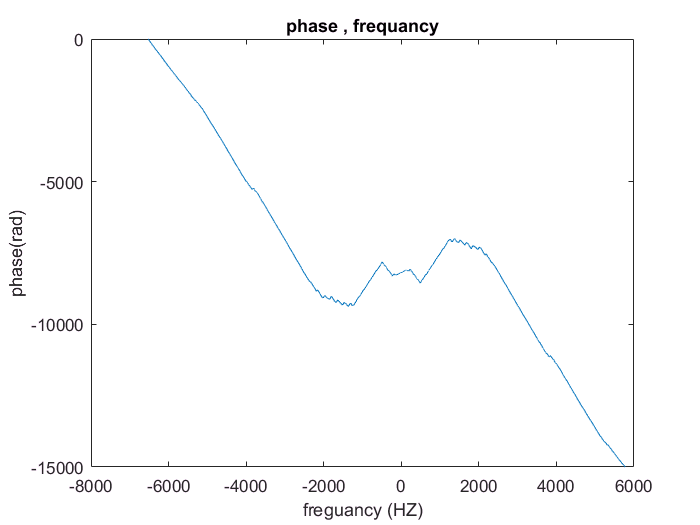

[y,fs]= audioread('data.wav');
sound(y,fs);
l = length(y);
t = -(((l-1)/fs)/2):1/fs:(((l-1)/fs)/2) ;
Y = fft(y);
Y = fftshift(Y);
f = -((length(Y)-1)/2):((length(Y)-1)/2);
A = abs(Y/length(Y));
P = angle(Y);
P = unwrap(P);
plot(f, P);
ylim([-15000 0]);



title('phase , frequancy')
xlabel('freguancy (HZ)')
ylabel('phase(rad)')

[y,fs]= audioread('data.wav');
sound(y,fs);
l = length(y);
t = -(((l-1)/fs)/2):1/fs:(((l-1)/fs)/2) ;
figure
plot(t,y);
title('signal , time')
xlabel('time (t)')
ylabel('signal')

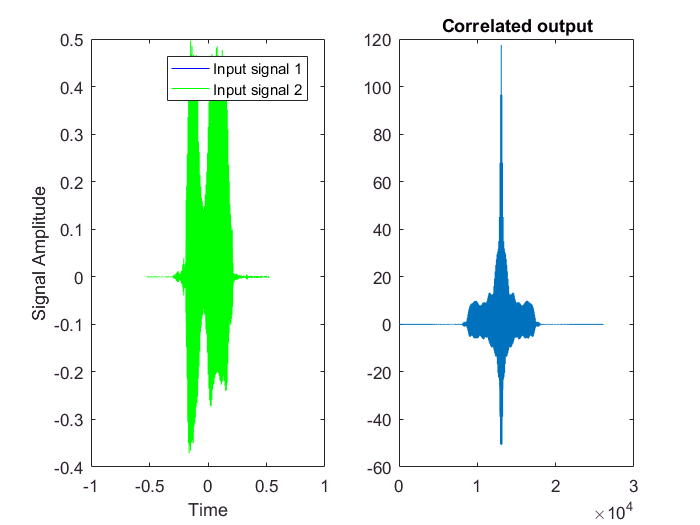

figure
y1=dspcross(y,y,fs);
subplot(1,2,2)
plot(y1);
title('Correlated output');

figure
convcross(y,y,fs);

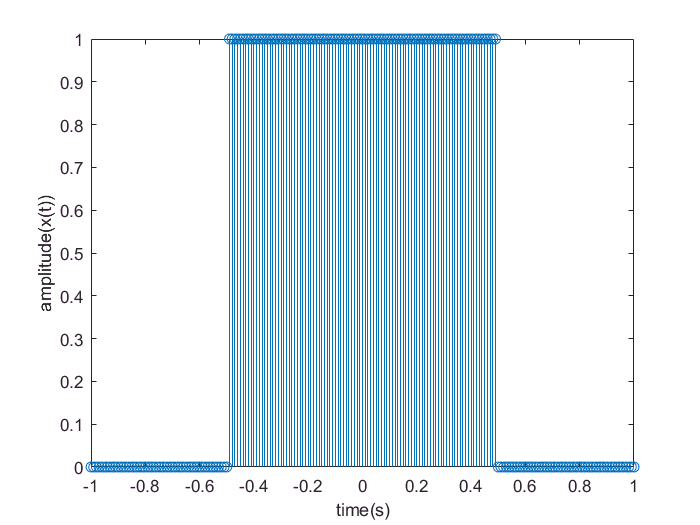



rect = @(t,a) ones(1,numel(t)).*(abs(t)<a/2); % a is the width of the pulse
t =-1:0.01:1;
x1=rect(t,1);
figure
stem(t,x1,'-');
xlabel('time(s)')
ylabel('amplitude(x(t))')

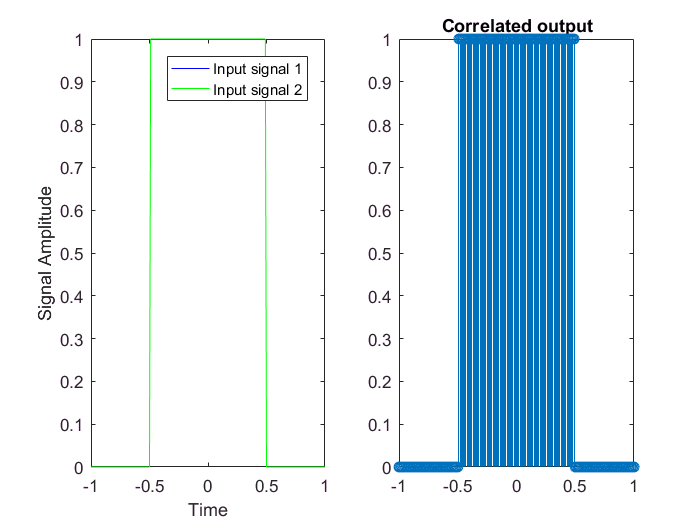

y1=dspcross(x1,x1,100);
subplot(1,2,2)
stem(t,y1);
title('Correlated output');

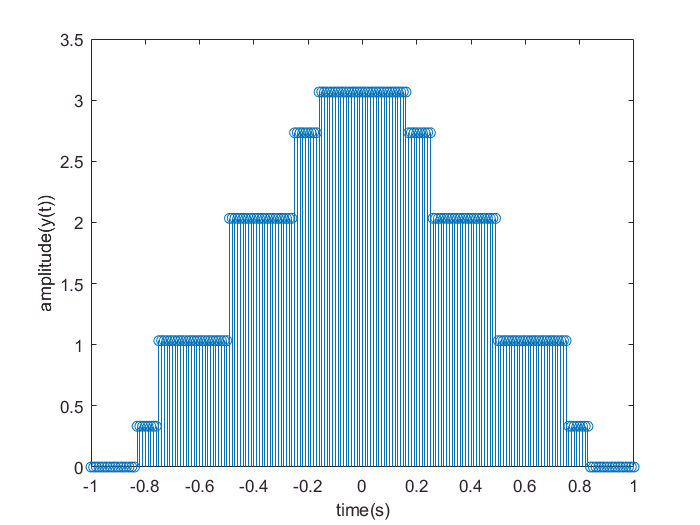

x2=rectangularPulse(-1/4,3/4,t);
x3=rectangularPulse(-3/4,1/4,t);
x4=rectangularPulse(-1/6,5/6,t);
x5=rectangularPulse(-5/6,1/6,t);
y=x1 + (0.7)*x2 + (0.7)*x3 + (1/3)*x4 + (1/3)*x5;
figure
stem(t,y);
xlabel('time(s)')
ylabel('amplitude(y(t))')

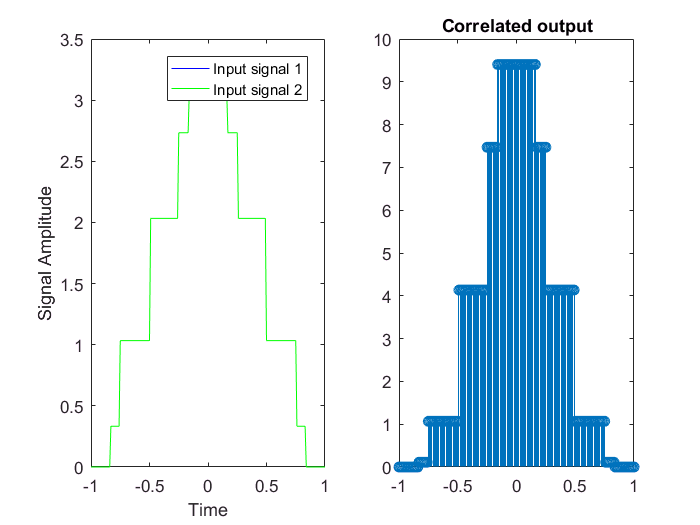

figure
y2=dspcross(y,y,100);
subplot(1,2,2)
stem(t,y2);
title('Correlated output');

%calculating the energy of a signal in time domain
rect = @(t,a) ones(1,numel(t)).*(abs(t)<a/2); % a is the width of the pulse
t =-1:0.01:1;
x1=rect(t,1);
fun = @(t) rect(t,1).*conj(rect(t,1));
Et = integral(fun,-Inf,Inf);
%calculating energy of a signal bt R(0)
figure
r =  dspcross(x1,x1,100);
E0 =r( ((length(t)-1)/2)+1);
subplot(1,2,2)
stem(t,r);
title('Correlated output');

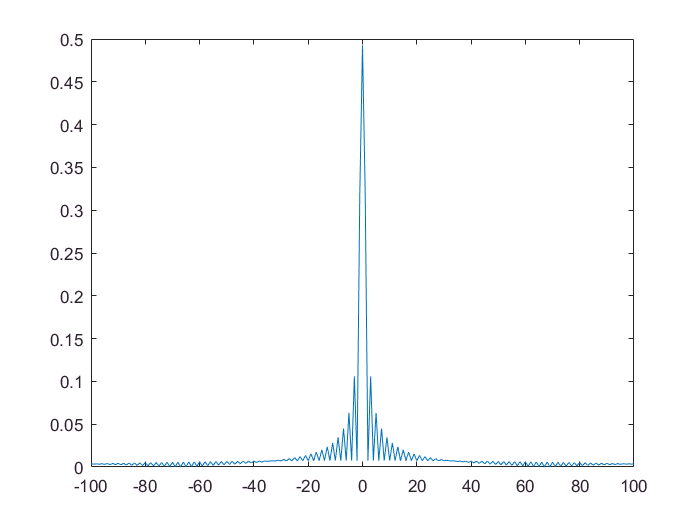

%Density of Spectrum
Rv = fft(r);
Rv = fftshift(Rv);
f = -100:100;
Rv = abs(Rv/length(Rv));
figure
plot(f,Rv);

Title=('Gv(f)')

Title = Gv(f)

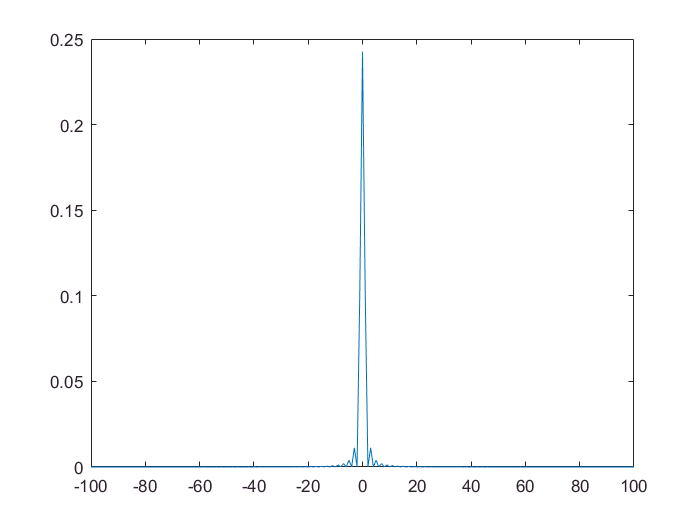

energy1 = trapz(f,Rv);


X1 = fft(x1);
X1 = fftshift(X1);
X1 = abs(X1/length(X1));
X1 = X1.*X1;
figure
plot(f,X1);

energy2 = trapz(f,X1);
title=('Vf')

title = Vf

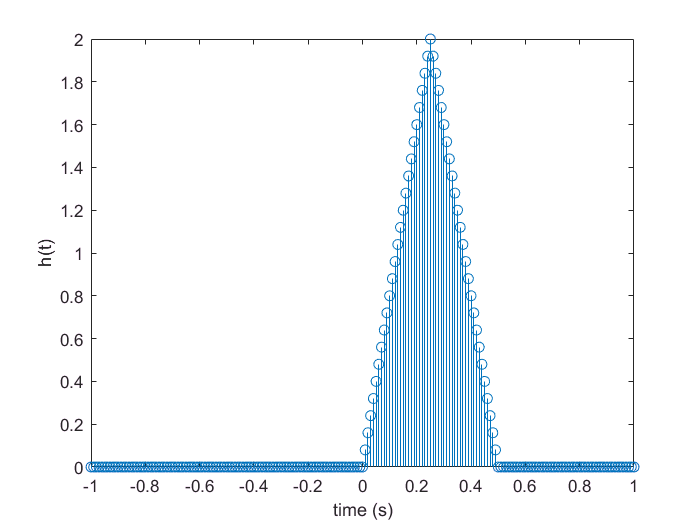

syms t;
h = @(t) 2.*(triangularPulse(0,1/4,1/2,t));
t = -1:0.01:1;
f=h(t);
stem(t,f);

xlabel('time (s)')
ylabel('h(t)')

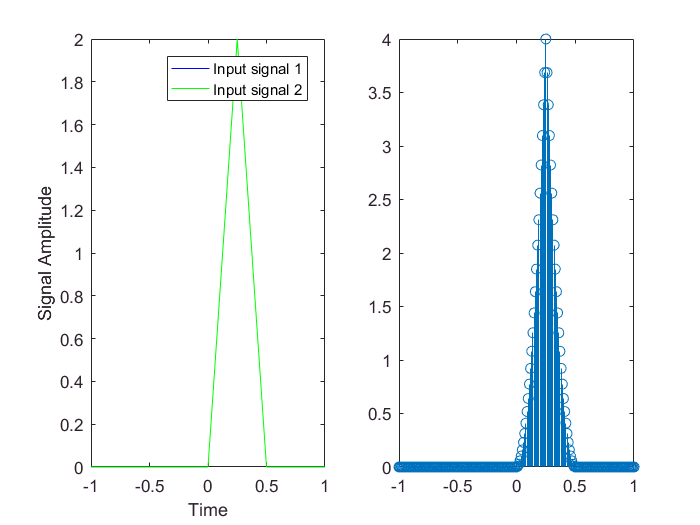

syms t;
h = @(t) 2.*(triangularPulse(0,1/4,1/2,t));
t = -1:0.01:1;
f=h(t);
Rv=dspcross(f,f,100);
subplot(1,2,2)
stem(t,Rv);

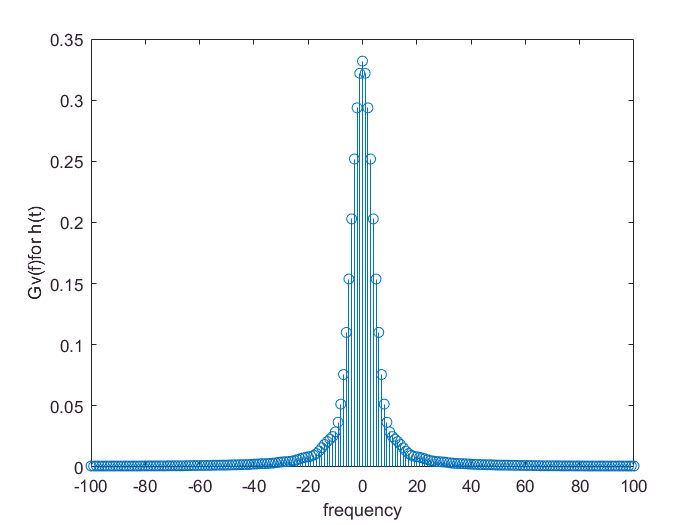


subplot(1,1,1)
RV = fft(Rv);
RV = fftshift(RV);
f = -((length(RV)-1)/2):((length(RV)-1)/2);
RV = abs(RV/length(RV));
stem(f,RV);
xlabel('frequency')
ylabel('Gv(f)for h(t)')

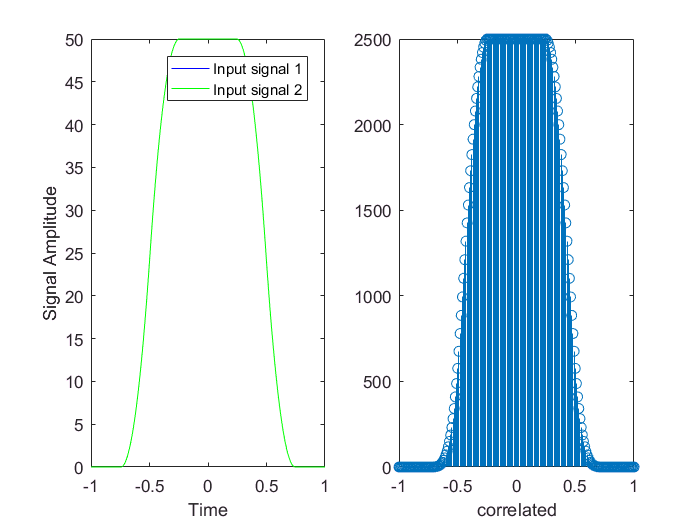

syms t;
fu = @(t) 2.*(triangularPulse(0,1/4,1/2,t));
rect = @(t,a) ones(1,numel(t)).*(abs(t)<a/2); % a is the width of the pulse
t = -1:0.01:1;
h=fu(t);
x1=rect(t,1);
y2=conv(x1,h);
y1=zeros(1,201);
for i=126:326
    y1(i-125)=y2(i);
end
figure
Ry1=dspcross(y1,y1,100);
subplot(1,2,2)
stem(t,Ry1);
xlabel('correlated')

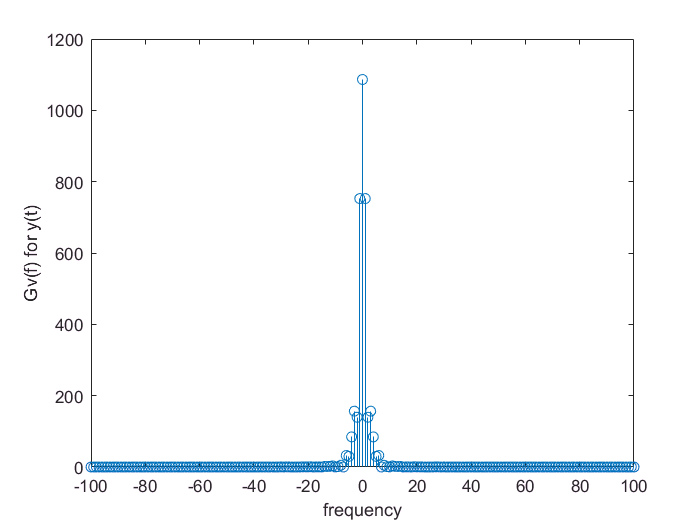


figure
RY1 = fft(Ry1);
RY1 = fftshift(RY1);
f = -((length(RY1)-1)/2):((length(RY1)-1)/2);
RY1 = abs(RY1/length(RY1));
stem(f,RY1);
xlabel('frequency')
ylabel('Gv(f) for y(t)')

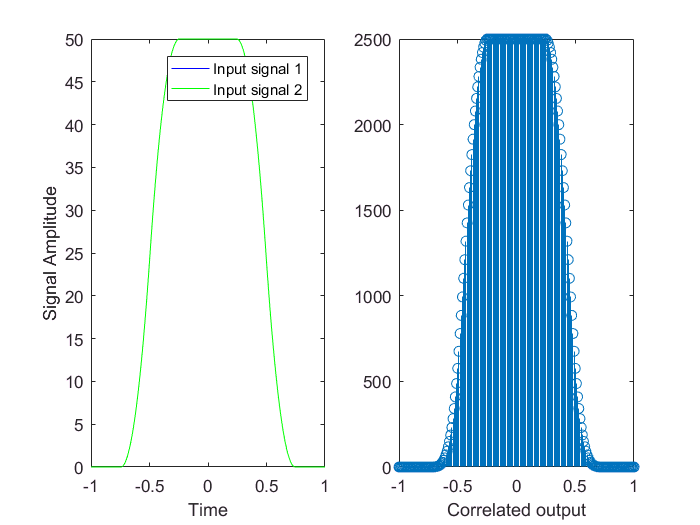

syms t;
fu = @(t) 2.*(triangularPulse(0,1/4,1/2,t));
rect = @(t,a) ones(1,numel(t)).*(abs(t)<a/2); % a is the width of the pulse
t = -1:0.01:1;
h=fu(t);
x1=rect(t,1);
y2=conv(x1,h);
y1=zeros(1,201);
for i=126:326
    y1(i-125)=y2(i);
end
figure
Ry1=dspcross(y1,y1,100);
subplot(1,2,2)
stem(t,Ry1);
xlabel('Correlated output(left side)');

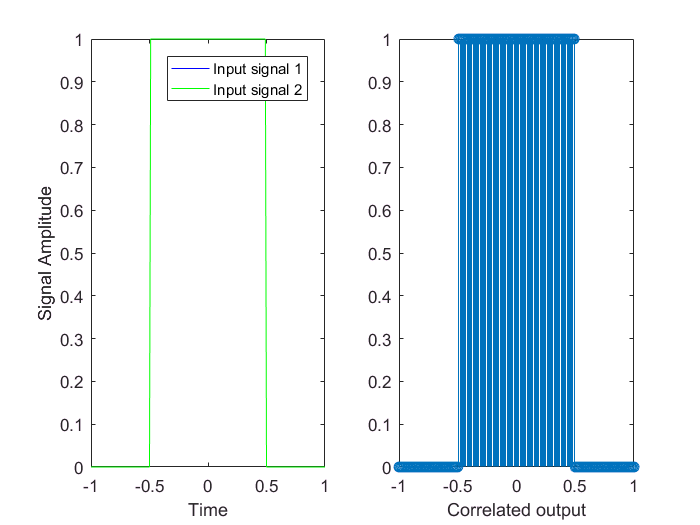

figure
Rx1 = dspcross(x1,x1,100);
subplot(1,2,2)
stem(t,Rx1);
xlabel('Correlated output');

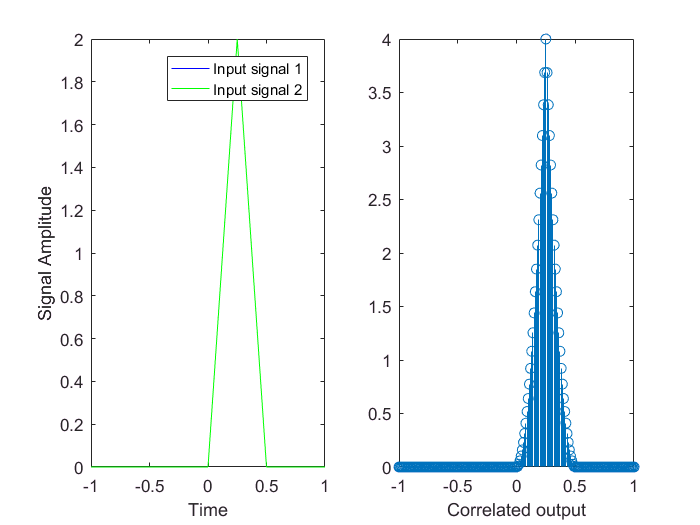

figure
Rh  = dspcross(h,h,100);
subplot(1,2,2)
stem(t,Rh);
xlabel('Correlated output');

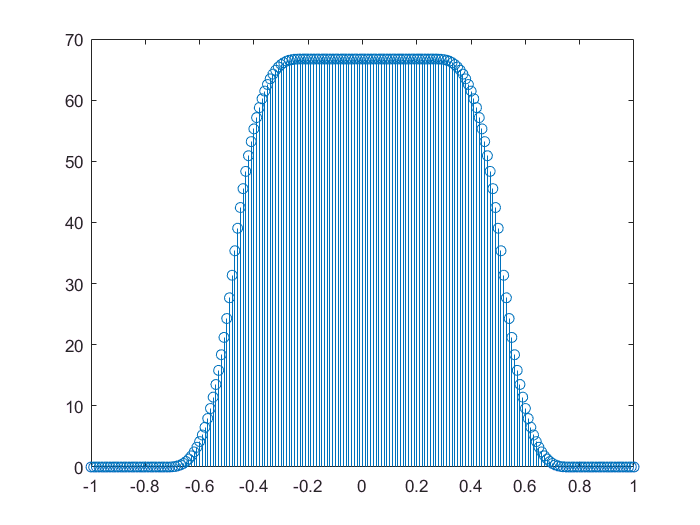

figure
Ry2=conv(Rx1,Rh);
Ry22=zeros(1,201);
for i=124:324
    Ry22(i-123)=Ry2(i);
end
stem(t,Ry22);

xlabel('Conv output(right side)')


syms t;
fu = @(t) 2.*(triangularPulse(0,1/4,1/2,t));
rect = @(t,a) ones(1,numel(t)).*(abs(t)<a/2); % a is the width of the pulse
t = -1:0.01:1;
h=fu(t);
x1=rect(t,1);
y2=conv(x1,h);
y1=zeros(1,201);
for i=126:326
    y1(i-125)=y2(i);
end
figure
Ry1=dspcross(y1,y1,100);
subplot(1,2,2)
stem(t,Ry1);
xlabel('Correlated output');

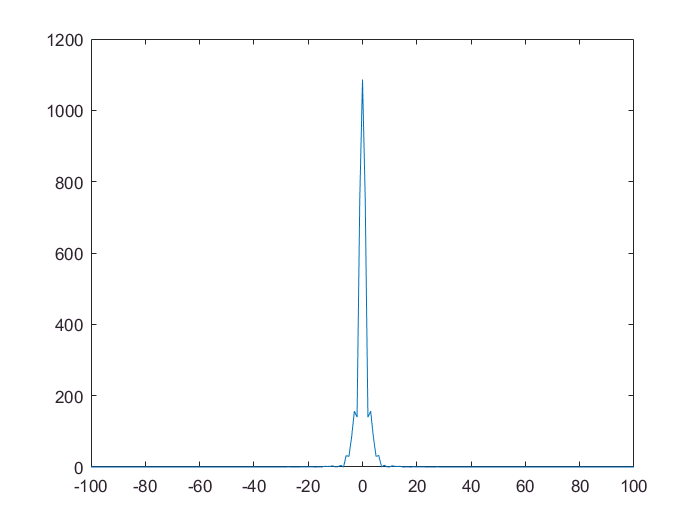

RY1 = fft(Ry1);
RY1 = fftshift(RY1);
RY1 = abs(RY1/length(RY1));
f = -100:100;
figure
plot(f,RY1);

title('fourier transform of Ry1(left side)')
figure
Rx1 = dspcross(x1,x1,100);
subplot(1,2,2)
stem(t,Rx1);
xlabel('Correlated output');

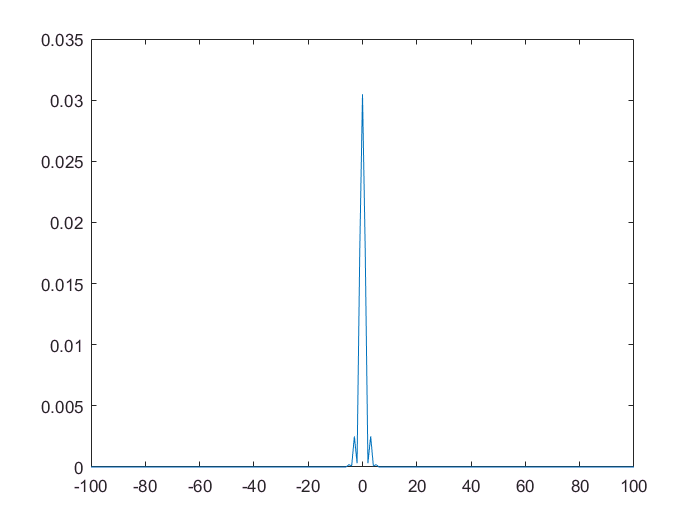

RX1 = fft(Rx1);
RX1 = fftshift(RX1);
RX1 = abs(RX1/length(RX1));

H1 = fft(h);
H1 = fftshift(H1);
H1 = abs(H1/length(H1));

H2= conj(H1);
RY2=RX1 .* H1 .* H2;
figure
plot(f,RY2);

title('fourier transform of Ry1(right side)')
